## Model Extension: Stochastic Life Cycle Model with Endogenous Labor

The representative consumer is born in period $0$ and lives up to $T-1$. Her working life is from period $0$ to $t_r-1$, where she receives exogenous labor income, $y_t$. From period $t_r$ onward, she is retired and receives a pension equal to some fraction, $0<\kappa<1$, of her labor income in the last period of her working life. She maximizes lifetime utility by choosing consumption and savings, subject to a dynamic budget constraint in each period. Her optimization problem is:


$$\underset{\{c_t\}_{t=1}^{T-1},\{n_t\}_{t=0}^{T-1} ,\{a_{t+1}\}_{t=0}^{T-1}}{\text{max }} U =  \sum_{t=1}^{T-1} \beta^{t}  \quad\left[\frac{c_t^{1-\sigma}}{1-\sigma} + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}} \right] \text{ ,}$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		G_t n_te^{(\rho \log y_{t-1} + \epsilon_t)} & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_t \geq 0,$$



$$a_0 \geq0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$



$$\begin{array}{r l} 1 = n_t + l_t \end{array} \$$


for all $t = 0, 1, ..., T-1$ and where $|\rho|<1$, $G_t$ is age-specific average of income and $\epsilon_t\sim\mathcal{N}(0,\sigma^2)$. The consumer has an initial wealth endowment, $a_0\geq0$, and the real interest rate, $r$, is fixed. Given an endowment of one unit of time, part of it can go to labor $n_t$ and the rest will go to leisure $l_t$. Consumers derive utility from leisure but must supply labor to produce the final good.

## Recursive Formulation.

The recursive formulation is


$$V_t(a_t,t,y_t) = \underset{c_t, n_t, a_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma}  + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}}+  \beta V_{t+1}(a_{t+1},t+1,y_{t+1}) \ ,$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
	       G_t n_te^{(\rho \log y_{t-1} + \epsilon_t)} & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_t \geq 0,$$



$$a_0 \geq0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


 $\begin{array}{r l} 1 = n_t + l_t \end{array} \$.

The state space consists only of $a_t$ while the choice space consists of $c_t$ and $a_{t+1}$. Substituting the budget constraint into the utility function gives


$$V_t(a_t,t,y_t, n_t) = \underset{a_{t+1}, n_{t+1}}{\text{max}}\frac{\left[a_t+y_t-\frac{a_{t+1}}{1+r}\right]^{1-\sigma}}{1-\sigma} + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}} + \beta V_{t+1}(a_{t+1},t+1,y_{t+1}) \ ,$$



$$y_t = \begin{cases}
		G_t n_t e^{(\rho \log y_{t-1} + \epsilon_t)} & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_t \geq 0,$$



$$a_0 \geq0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


$\begin{array}{r l} 1 = n_t + l_t \end{array} \$.

which reduces the choice space to $a_{t+1}$.

## Set the parameters and generate the state space.

Calls: model2.m.

As before, we cannot directly compute the steady state capital because of the productivity fluctuations, but we can still build the grid for $k_t$ around the deterministic steady state.

clc
clear
close all

main = strcat('C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current  working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model 



par = model2.setup; % Set parameters.
par = model2.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration.

Calls: solve2.m, and model2.m.

Note that the allocation of labor and leisure is a static decision. From (5.23) in Adda and Cooper, the intratemporal is


$$c_t^{-\sigma} G_t n_t e^{(\rho \log y_{t-1} + \epsilon_t)}  = -\gamma(1-n_t)^{\frac{1}{\nu}} \ .$$


We have pre-determined grids for $a_t$, and we use the same grid for $a_{t+1}$ as $a_t$. Given these and the equation above, we can $n_t$ by using a numerical solver to minimize


$$f(n_t) =c_t^{-\sigma}G_t n_t e^{(\rho \log y_{t-1} + \epsilon_t)} + \gamma(1-n_t)^{\frac{1}{\nu}} \ ,$$


and obtain optimal labor supply given any combination of the state variables and any potential choice of $a_{t+1}$ associated with these. Crucially, we can do this outside of the value function iteration algorithm because the decision is static. Once we have the optimal $n_t$, we can treat this as a parameter for each combination of $a_t, a_{t+1},$ and $y_t$.

t = cputime;
sol = solve2.lc(par); % Solve the model using Value Function Iteration.

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 108.7656 seconds.


## Simulate the model and plot the model functions and time series.

Calls: simulate2.m and my_graph2.m.

sim = simulate2.lc(par,sol); % Simulate the model.
my_graph2.plot_policy(par,sol,sim, figout) % Plot the model functions and time series.

### Simulate the extension model for different values of  $\beta$ and  $\gamma$

%% Run Scenarios 
% Define parameter values
betas = [0.90, 0.92, 0.94, 0.96];

% Create figure with 2 subplots
figure;

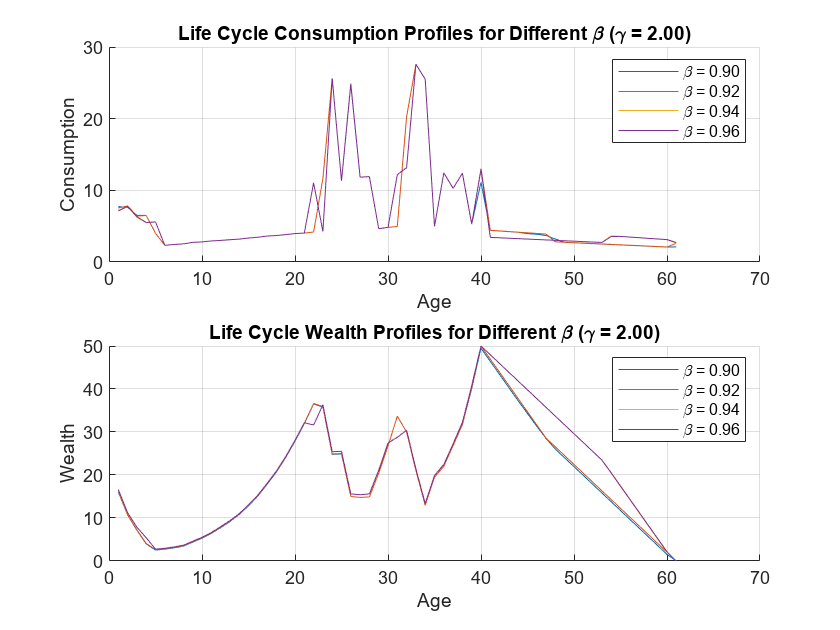

colors = lines(length(betas));

% Initialize storage for all lines
cons_data = nan(length(betas), 100); % Assuming T ≤ 100
asset_data = nan(length(betas), 100);
T_max = 0;

for i = 1:length(betas)
    par = model2.setup;
    par = model2.gen_grids(par); 
    par.beta = betas(i);
    par.sigma = 2.00;
    sol = solve2.lc(par);
    sim = simulate2.lc(par, sol);

    T_max = max(T_max, par.T);

    % Initialize storage
    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
        lcp_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end

    % Store data for plotting
    cons_data(i,1:par.T) = lcp_c;
    asset_data(i,1:par.T) = lcp_a;
end
%% Subplot 1: Consumption
subplot(2,1,1);
hold on;
for i = 1:length(betas)
    plot(1:T_max, cons_data(i,1:T_max), 'Color', colors(i,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\beta = %.2f', betas(i)));
end
xlabel('Age');
ylabel('Consumption');
title('Life Cycle Consumption Profiles for Different \beta (\gamma = 2.00)');
legend('show', 'Location', 'best');
grid on;
hold off;

%% Subplot 2: Wealth
subplot(2,1,2);
hold on;
for i = 1:length(betas)
    plot(1:T_max, asset_data(i,1:T_max), 'Color', colors(i,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\beta = %.2f', betas(i)));
end
xlabel('Age');
ylabel('Wealth');
title('Life Cycle Wealth Profiles for Different \beta (\gamma = 2.00)');
legend('show', 'Location', 'best');
grid on;
hold off;
saveas(gcf, fullfile(figout, 'sim4.png'))

%% Plot life cycle profiles for different gamma values
gammas = [2.00, 3.00, 4.00, 5.00];

% Create figure with 2 subplots
figure;
colors = lines(length(gammas));

% Storage for max age
T_max = 0;
cons_data = nan(length(gammas), 100); % Assuming max T ≤ 100
asset_data = nan(length(gammas), 100);

for j = 1:length(gammas)
    par = model2.setup;
    par = model2.gen_grids(par); 
    par.gamma = gammas(j);
    par.beta = 0.96;
    sol = solve2.lc(par);
    sim = simulate.lc(par, sol);

    T_max = max(T_max, par.T);

    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        indices = (sim.tsim == t);
        lcp_c(t) = mean(sim.csim(indices), 'omitnan');
        lcp_a(t) = mean(sim.asim(indices), 'omitnan');
    end

    cons_data(j,1:par.T) = lcp_c;
    asset_data(j,1:par.T) = lcp_a;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


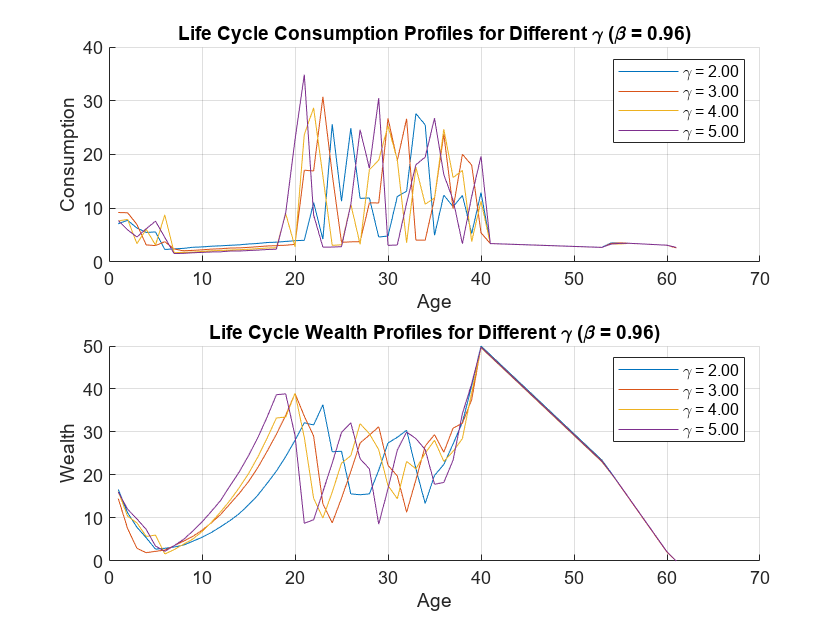

%% Subplot 1: Consumption
subplot(2,1,1);
hold on;
for j = 1:length(gammas)
    plot(1:T_max, cons_data(j,1:T_max), 'Color', colors(j,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\gamma = %.2f', gammas(j)));
end
xlabel('Age');
ylabel('Consumption');
title('Life Cycle Consumption Profiles for Different \gamma (\beta = 0.96)');
legend('show', 'Location', 'best');
grid on;
hold off;

%% Subplot 2: Wealth
subplot(2,1,2);
hold on;
for j = 1:length(gammas)
    plot(1:T_max, asset_data(j,1:T_max), 'Color', colors(j,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\gamma = %.2f', gammas(j)));
end
xlabel('Age');
ylabel('Wealth');
title('Life Cycle Wealth Profiles for Different \gamma (\beta = 0.96)');
legend('show', 'Location', 'best');
grid on;
hold off;
saveas(gcf, fullfile(figout, 'sim5.png'))


%% Compute and plot heatmap of average simulated wealth
avg_wealth = nan(length(betas), length(gammas)); % Ensure NaN initialization

for i = 1:length(betas)
    for j = 1:length(gammas)
        % Initialize and update parameters
        par = model2.setup;
        par = model2.gen_grids(par);
        par.beta = betas(i);
        par.sigma = gammas(j);

        % Solve model for given parameters
        sol = solve2.lc(par);
        sim = simulate2.lc(par, sol);

        % Compute average wealth
        avg_wealth(i,j) = mean(sim.asim(:), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.

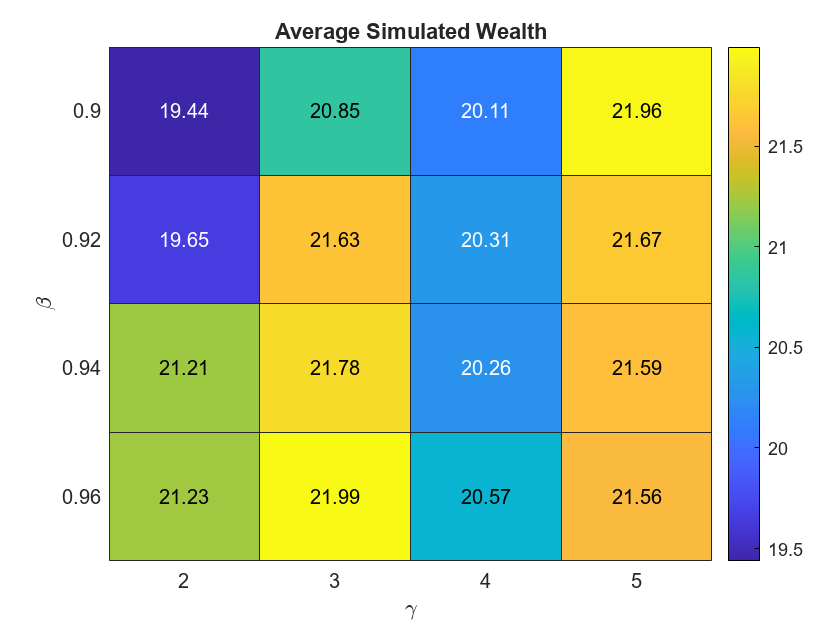


% Create heatmap
figure;
h = heatmap(string(gammas), string(betas), avg_wealth, 'Colormap', parula);
xlabel('\gamma');
ylabel('\beta');
title('Average Simulated Wealth');
saveas(gcf, fullfile(figout, 'sim6.png'))

### Descriptive Statistics for comparison of different values of $\beta$ and  $\gamma$

%% Define parameter values
betas = [0.90, 0.92, 0.94, 0.96];
gammas = [2.00, 3.00, 4.00, 5.00];

% Initialize storage for all data
cons_data = nan(length(betas), 100);  % Assuming T_max ≤ 100
asset_data = nan(length(betas), 100);
T_max = 0;

% Initialize structure for storing descriptive statistics
descriptive_stats = struct();

%% Loop over different betas to calculate consumption and wealth
for i = 1:length(betas)
    par = model2.setup;
    par = model2.gen_grids(par); 
    par.beta = betas(i);
    par.sigma = 2.00;
    sol = solve2.lc(par);
    sim = simulate2.lc(par, sol);

    T_max = max(T_max, par.T);

    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
        lcp_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end

    cons_data(i,1:par.T) = lcp_c;
    asset_data(i,1:par.T) = lcp_a;

    % Calculate descriptive statistics for consumption
    cons_mean = mean(cons_data(i, 1:T_max), 'omitnan');
    cons_std = std(cons_data(i, 1:T_max), 'omitnan');
    cons_min = min(cons_data(i, 1:T_max), [], 'omitnan');
    cons_max = max(cons_data(i, 1:T_max), [], 'omitnan');
    cons_median = median(cons_data(i, 1:T_max), 'omitnan');

    % Store statistics for consumption
    descriptive_stats.beta(i).cons_mean = cons_mean;
    descriptive_stats.beta(i).cons_std = cons_std;
    descriptive_stats.beta(i).cons_min = cons_min;
    descriptive_stats.beta(i).cons_max = cons_max;
    descriptive_stats.beta(i).cons_median = cons_median;

    % Calculate descriptive statistics for wealth
    wealth_mean = mean(asset_data(i, 1:T_max), 'omitnan');
    wealth_std = std(asset_data(i, 1:T_max), 'omitnan');
    wealth_min = min(asset_data(i, 1:T_max), [], 'omitnan');
    wealth_max = max(asset_data(i, 1:T_max), [], 'omitnan');
    wealth_median = median(asset_data(i, 1:T_max), 'omitnan');

    % Store statistics for wealth
    descriptive_stats.beta(i).wealth_mean = wealth_mean;
    descriptive_stats.beta(i).wealth_std = wealth_std;
    descriptive_stats.beta(i).wealth_min = wealth_min;
    descriptive_stats.beta(i).wealth_max = wealth_max;
    descriptive_stats.beta(i).wealth_median = wealth_median;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------



%% Display Descriptive Statistics for Consumption
cons_table = table();
cons_table.Beta = betas';
cons_table.Mean = [descriptive_stats.beta(:).cons_mean]';
cons_table.StdDev = [descriptive_stats.beta(:).cons_std]';
cons_table.Min = [descriptive_stats.beta(:).cons_min]';
cons_table.Max = [descriptive_stats.beta(:).cons_max]';
cons_table.Median = [descriptive_stats.beta(:).cons_median]';

disp('Descriptive Statistics for Consumption for different values of betas:');

Descriptive Statistics for Consumption for different values of betas:


disp(cons_table);

    Beta     Mean     StdDev     Min       Max      Median
    ____    ______    ______    ______    ______    ______

     0.9    6.4257    6.3094    2.0854      27.6    3.9578
    0.92      6.47    6.3357    2.1003      27.6    3.9826
    0.94    6.5065    6.1238    2.3258    27.598    3.5665
    0.96    6.5069    6.1231    2.3258    27.598    3.5566



%% Display Descriptive Statistics for Consumption
wealth_table = table();
wealth_table.Beta = betas';
wealth_table.Mean = [descriptive_stats.beta(:).wealth_mean]';
wealth_table.StdDev = [descriptive_stats.beta(:).wealth_std]';
wealth_table.Min = [descriptive_stats.beta(:).wealth_min]';
wealth_table.Max = [descriptive_stats.beta(:).wealth_max]';
wealth_table.Median = [descriptive_stats.beta(:).wealth_median]';

disp('Descriptive Statistics for Wealth for different values of betas:');

Descriptive Statistics for Wealth for different values of betas:


disp(wealth_table);

    Beta     Mean     StdDev    Min     Max     Median
    ____    ______    ______    ___    _____    ______

     0.9    19.438    12.568     0     49.49    17.857
    0.92    19.649    12.607     0        50    18.367
    0.94    21.214    13.093     0        50    20.918
    0.96     21.23    13.082     0        50    20.918





%% Loop over different gammas to calculate consumption and wealth
cons_data = nan(length(gammas), 100);  % Reset storage for consumption data
asset_data = nan(length(gammas), 100);  % Reset storage for asset data
T_max = 0;

for j = 1:length(gammas)
    par = model2.setup;
    par = model2.gen_grids(par); 
    par.sigma = gammas(j);
    par.beta = 0.96;
    sol = solve2.lc(par);
    sim = simulate2.lc(par, sol);

    T_max = max(T_max, par.T);

    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        indices = (sim.tsim == t);
        lcp_c(t) = mean(sim.csim(indices), 'omitnan');
        lcp_a(t) = mean(sim.asim(indices), 'omitnan');
    end

    cons_data(j,1:par.T) = lcp_c;
    asset_data(j,1:par.T) = lcp_a;

    % Calculate descriptive statistics for consumption
    cons_mean = mean(cons_data(j, 1:T_max), 'omitnan');
    cons_std = std(cons_data(j, 1:T_max), 'omitnan');
    cons_min = min(cons_data(j, 1:T_max), [], 'omitnan');
    cons_max = max(cons_data(j, 1:T_max), [], 'omitnan');
    cons_median = median(cons_data(j, 1:T_max), 'omitnan');

    % Store statistics for consumption
    descriptive_stats.gamma(j).cons_mean = cons_mean;
    descriptive_stats.gamma(j).cons_std = cons_std;
    descriptive_stats.gamma(j).cons_min = cons_min;
    descriptive_stats.gamma(j).cons_max = cons_max;
    descriptive_stats.gamma(j).cons_median = cons_median;

    % Calculate descriptive statistics for wealth
    wealth_mean = mean(asset_data(j, 1:T_max), 'omitnan');
    wealth_std = std(asset_data(j, 1:T_max), 'omitnan');
    wealth_min = min(asset_data(j, 1:T_max), [], 'omitnan');
    wealth_max = max(asset_data(j, 1:T_max), [], 'omitnan');
    wealth_median = median(asset_data(j, 1:T_max), 'omitnan');

    % Store statistics for wealth
    descriptive_stats.gamma(j).wealth_mean = wealth_mean;
    descriptive_stats.gamma(j).wealth_std = wealth_std;
    descriptive_stats.gamma(j).wealth_min = wealth_min;
    descriptive_stats.gamma(j).wealth_max = wealth_max;
    descriptive_stats.gamma(j).wealth_median = wealth_median;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


%% Display Descriptive Statistics for Consumption
consp_table = table();
consp_table.Gamma = gammas';
consp_table.Mean = [descriptive_stats.gamma(:).wealth_mean]';
consp_table.StdDev = [descriptive_stats.gamma(:).wealth_std]';
consp_table.Min = [descriptive_stats.gamma(:).wealth_min]';
consp_table.Max = [descriptive_stats.gamma(:).wealth_max]';
consp_table.Median = [descriptive_stats.gamma(:).wealth_median]';

disp('Descriptive Statistics for Consumption with different gammas:');

Descriptive Statistics for Consumption with different gammas:


disp(consp_table);

    Gamma     Mean     StdDev    Min     Max      Median
    _____    ______    ______    ___    ______    ______

      2       21.23    13.082     0         50    20.918
      3      21.992    10.545     0     47.245    21.837
      4       20.57    10.951     0     45.306    22.143
      5      21.557    9.7962     0     46.531    19.592




%% Display Descriptive Statistics for Wealth
wealth_table = table();
wealth_table.Gamma = gammas';
wealth_table.Mean = [descriptive_stats.gamma(:).cons_mean]';
wealth_table.StdDev = [descriptive_stats.gamma(:).cons_std]';
wealth_table.Min = [descriptive_stats.gamma(:).cons_min]';
wealth_table.Max = [descriptive_stats.gamma(:).cons_max]';
wealth_table.Median = [descriptive_stats.gamma(:).cons_median]';

disp('Descriptive Statistics for Wealth with different gammas:');

Descriptive Statistics for Wealth with different gammasD:


disp(wealth_table);

    Gamma     Mean     StdDev     Min       Max      Median
    _____    ______    ______    ______    ______    ______

      2      6.5069    6.1231    2.3258    27.598    3.5566
      3      7.4258    7.2159    1.7947    26.375    3.1197
      4      8.1949    7.2614    1.6639    25.447    3.3465
      5      9.0939    8.8466    1.4545    35.827     4.483

